# PubChem_Similarity

Search for chemical structures in PubChem via a Fingerprint Tanimoto Similarity Search

% Vincent F. Scalfani, Serena C. Ralph, and Jason E. Bara 
% The University of Alabama
% Tested with MATLAB R2020a, running Ubuntu 18.04 on March 30, 2020.

## Define the PubChem API base URL

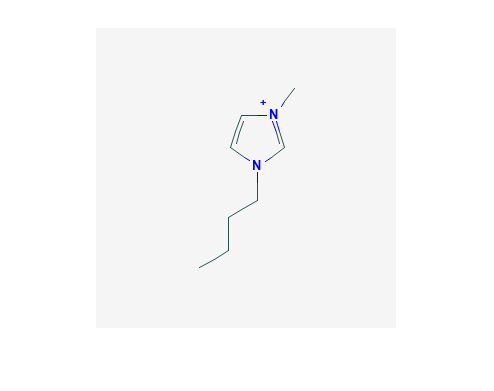

% PubChem API
api = 'https://pubchem.ncbi.nlm.nih.gov/rest/pug/compound/';

% set MATLAB web options to a 30 second timeout
options = weboptions('Timeout', 30);

% Retrieve and display PNG Image of 1-Butyl-3-methyl-imidazolium; CID = 2734162
CID_SS_query = '2734162';

CID_url = [api 'cid/' CID_SS_query '/PNG'];
[CID_img,map] = imread(CID_url);
imshow(CID_img,map)

*Replace the above CID value (CID_SS_query) with a different CID to customize.*

## Retrieve InChI and SMILES

% Retrieve InChI
inchi_url = [api 'cid/' CID_SS_query '/property/inchi/TXT'];
inchi = webread(inchi_url, options);
disp(inchi)

InChI=1S/C8H15N2/c1-3-4-5-10-7-6-9(2)8-10/h6-8H,3-5H2,1-2H3/q+1



% Retrieve Isomeric SMILES
IS_url = [api 'cid/' CID_SS_query '/property/IsomericSMILES/TXT'];
IS = webread(IS_url, options);
disp(IS)

CCCCN1C=C[N+](=C1)C



## Perform a Similarity Search

% Search for chemical structures by Similarity Search (SS), 
% (2D Tanimoto threshold 95% to 1-Butyl-3-methyl-imidazolium; CID = 2734162)
api = 'https://pubchem.ncbi.nlm.nih.gov/rest/pug/compound/';
SS_url = [api 'fastsimilarity_2d/cid/' CID_SS_query '/cids/JSON?Threshold=95'];
SS_CIDs = webread(SS_url,options);
SS_CIDs = num2cell(SS_CIDs.IdentifierList.CID)

SS_CIDs = 249×1 cell array
    {[12971008]}
    {[  304622]}
    {[   61347]}
    {[11448496]}
    {[11424151]}
    {[11171745]}
    {[ 2734161]}
    {[  118785]}
    {[ 2734236]}
    {[ 2734162]}
    {[  529334]}
    {[11788435]}
    {[11245926]}
    {[11160028]}
    {[ 5245884]}
    {[ 2734168]}


*In the above SS_url value, you can adjust to the desired Tanimoto threshold (i.e., 97, 90, etc.)*

% set a CID limit to 25 max

*The CID limit of 25 was added as an initial testing safety for time consideration. This limit can be increased.*

number_SS_CIDs = length(SS_CIDs)

number_SS_CIDs = 249

if number_SS_CIDs > 25
    SS_CIDs = SS_CIDs(1:25)  
else
    disp('Number of SS_CIDs not changed')    
end

SS_CIDs = 25×1 cell array
    {[12971008]}
    {[  304622]}
    {[   61347]}
    {[11448496]}
    {[11424151]}
    {[11171745]}
    {[ 2734161]}
    {[  118785]}
    {[ 2734236]}
    {[ 2734162]}
    {[  529334]}
    {[11788435]}
    {[11245926]}
    {[11160028]}
    {[ 5245884]}
    {[ 2734168]}


## Retrieve Identifier and Property Data

% Create an identifier/property dataset from Similarity Search results
% Retrieve the following data from CID hit results:
% InChI, Isomeric SMILES, MW, Heavy Atom Count, Rotable Bond Count, and
% Charge

% setup a for loop that processes each CID one-by-one
for r = 1:length(SS_CIDs)
    CID = SS_CIDs{r};
    
    % define api calls
    api = 'https://pubchem.ncbi.nlm.nih.gov/rest/pug/compound/';
    CID_InChI_url = [api 'cid/' num2str(CID) '/property/InChI/TXT'];
    CID_IsoSMI_url = [api 'cid/' num2str(CID) '/property/IsomericSMILES/TXT'];
    CID_MW_url = [api 'cid/' num2str(CID) '/property/MolecularWeight/TXT'];  
    CID_HeavyAtomCount_url = [api 'cid/' num2str(CID) '/property/HeavyAtomCount/TXT'];
    CID_RotatableBondCount_url = [api 'cid/' num2str(CID) '/property/RotatableBondCount/TXT'];
    CID_Charge_url = [api 'cid/' num2str(CID) '/property/Charge/TXT'];

*Additional property data can be collected by defining new api calls, for example, if you want TPSA data:*

% CID_TPSA_url = [api 'cid/' num2str(CID) '/property/TPSA/TXT'];

    % retrieve identifer and property data
    try
        CID_InChI = webread(CID_InChI_url,options);      
    catch ME
        CID_InChI = 'not found'
    end
        % be polite to PubChem server
        n = 0.5;
        pause(n)
     
    try
        CID_IsoSMI = webread(CID_IsoSMI_url,options);     
    catch ME  
        CID_IsoSMI = 'not found'
    end
        n = 0.5;
        pause(n)
    
    try
        CID_MW = webread(CID_MW_url,options);
    catch ME
        CID_MW = 'not found'
    end    
        n = 0.5;
        pause(n)
            
    try
        CID_HeavyAtomCount = webread(CID_HeavyAtomCount_url,options);
    catch ME
        CID_HeavyAtomCount = 'not found'
    end
        n = 0.5;
        pause(n)
        
    try
        CID_RotatableBondCount = webread(CID_RotatableBondCount_url,options);
    catch ME
        CID_RotatableBondCount = 'not found'
    end
        n = 0.5;
        pause(n)
       
    try
        CID_Charge = webread(CID_Charge_url,options);
    catch ME
        CID_Charge = 'not found'
    end
        n = 0.5;
        pause(n)
        
      % add property data to SS_CIDs data array
      
      % column numbers indicate where the data will be stored.
      % For example, the MW will be placed in column 4. r increases
      % by 1 on each iteration, so the first CID_MW value gets stored in
      % {1,4}, the second in {2,4}, the third in {3,4}, etc.
        SS_CIDs{r,2} = CID_InChI;
        SS_CIDs{r,3} = CID_IsoSMI;
        SS_CIDs{r,4} = CID_MW;
        SS_CIDs{r,5} = CID_HeavyAtomCount;
        SS_CIDs{r,6} = CID_RotatableBondCount;
        SS_CIDs{r,7} = CID_Charge;
        
        % to add more data, simply index into the next column
        % SS_CIDs{r,8} = CID_TPSA;
                                       
end


## Compile Data into a Table

% convert cell array to string and remove leading and trailing white space
SS_CIDs_string = strtrim(string(SS_CIDs));

% convert to table
SSq_table = array2table(SS_CIDs_string, 'VariableNames',{'CID', 'InChI','IsoSMI','MW',...
    'HeavyAtomCount','RotatableBondCount','Charge'})

SSq_table = 25×7 table
       CID                                                 InChI                                                            IsoSMI                        MW         HeavyAtomCount    RotatableBondCount    Charge
    __________    ________________________________________________________________________________________    ___________________________________    ____________    ______________    __________________    ______

    "12971008"    "InChI=1S/C7H13N2.HI/c1-3-4-9-6-5-8(2)7-9;/h5-7H,3-4H2,1-2H3;1H/q+1;/p-1"                   "CCCN1C=C[N+](=C1)C.[I-]"              "252.100000"         "10"                "2"             "0"  
    "304622"      "InChI=1S/C8H14N2/c1-3-4-6-10-7-5-9-8(10)2/h5,7H,3-4,6H2,1-2H3"                     

% rearrange table
SSq_table2 = SSq_table(:, {'IsoSMI' 'CID' 'InChI' 'MW' 'HeavyAtomCount' 'RotatableBondCount' 'Charge'})

SSq_table2 = 25×7 table
                  IsoSMI                      CID                                                 InChI                                                   MW         HeavyAtomCount    RotatableBondCount    Charge
    ___________________________________    __________    ________________________________________________________________________________________    ____________    ______________    __________________    ______

    "CCCN1C=C[N+](=C1)C.[I-]"              "12971008"    "InChI=1S/C7H13N2.HI/c1-3-4-9-6-5-8(2)7-9;/h5-7H,3-4H2,1-2H3;1H/q+1;/p-1"                   "252.100000"         "10"                "2"             "0"  
    "CCCCN1C=CN=C1C"                       "304622"      "InChI=1S/C8H14N2/c1-3-4-6-10-7-5-9-8(10)2/h

% data export as tabbed text file
% prompt user to select folder for data export
save_folder = uigetdir;

% change directory to selected folder
cd(save_folder)

writetable(SSq_table2,'MATLAB_Similarityq_results.txt','Delimiter','tab')

## Retrieve Images of CID Compounds from Similarity Search

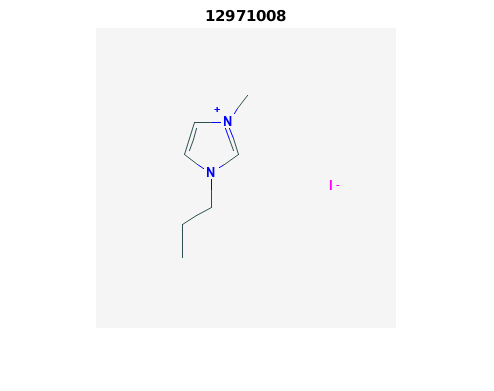

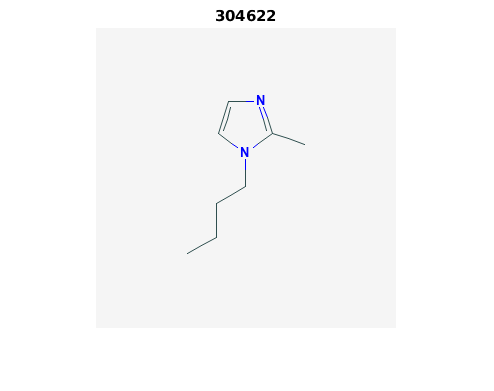

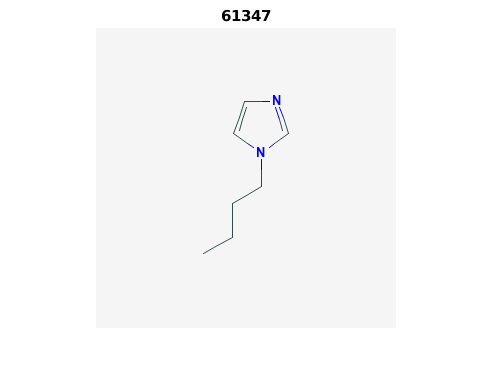

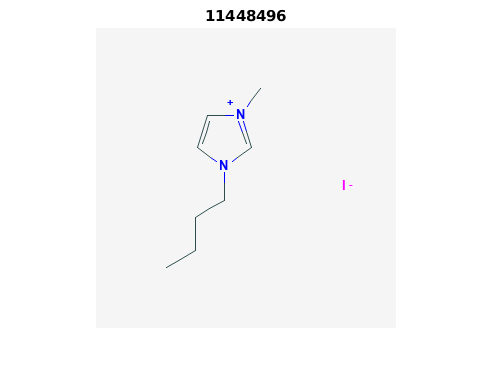

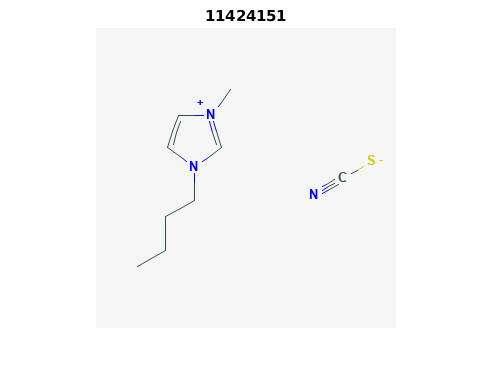

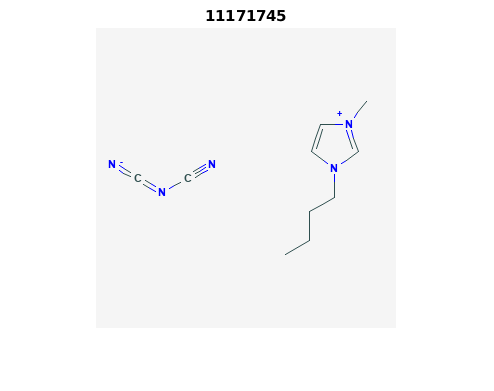

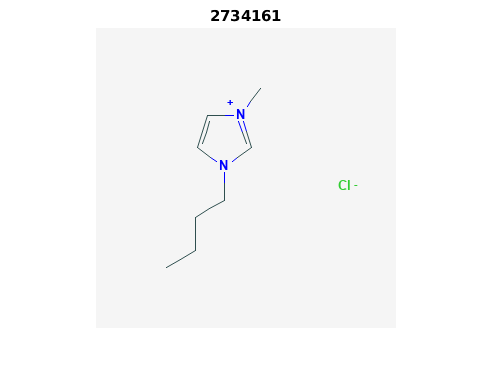

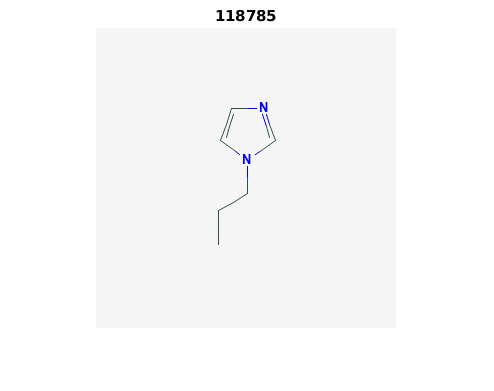

% loop through hit CIDs and show images
for r = 1:length(SS_CIDs)
    CID = SS_CIDs{r};
    api = 'https://pubchem.ncbi.nlm.nih.gov/rest/pug/compound/';
    CID_url = [api 'cid/' num2str(CID) '/PNG'];
    
    try
        % retrieve CID PNG image and display
        [CID_img,map] = imread(CID_url);
        figure;
        imshow(CID_img,map)
        drawnow;
        title(num2str(CID));
        
        % be polite to PubChem server
        n = 0.5;
        pause(n);
        
    catch
        disp('CID image not found')
        disp('Execution will continue')
    end
    
end